# Projekt 4

#### **Przykład 1**

Zmiana mapy kolorów obrazu rzeczywistego, kontrolowana przez użytkownika.

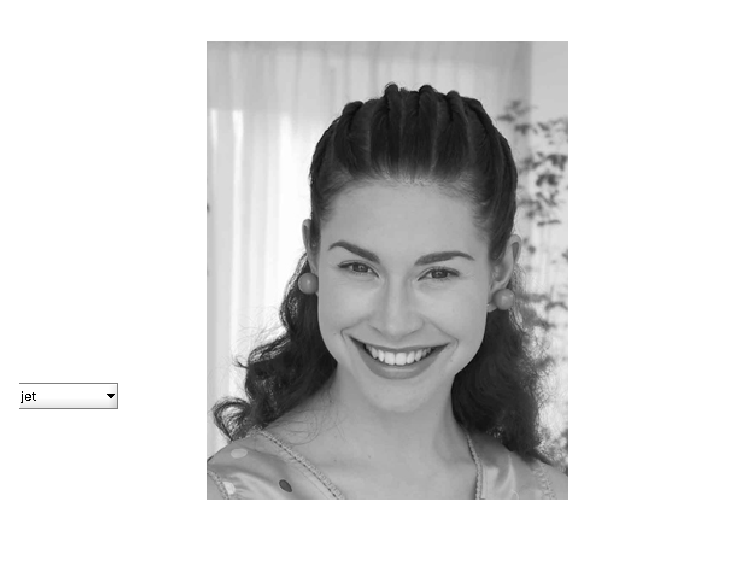

L1=imread('data/portret.jpg');
figure(1)
imshow(L1)

uicontrol(1,'Style', 'popup',...
           'String', 'jet|hsv',...
           'Position', [20 1 100 50],...
           'Callback', @setmap);

*uicontrol(1,'Style', 'popup',...*  *– 1 to uchwyt do okna, potem styl kontrolki, czyli lista rozwijana*

           *'String', 'jet|hsv',...*   *– opcje do wyświetlania w liście*

           *'Position', [20 1 100 50],...*  *– pozycja kontroli we współrzędnych kartezjańskich*

           *'Callback', @setmap);*  *- co ma się stać po wybraniu kontrolki – tu zewnętrzna funkcja*

*function setmap(h,event) – h to uchwyt do kontrolki (nie figury!), event - zdarzenie*

    *val = get(h,'Value');*  *- przechwycenie nowej wartość kontrolki*

### Zadanie 1

Stwórz okno składające się z dwóch części: w jednej będzie wyświetlany obraz *portret.jpg *z narzuconą mapą kolorów, w drugiej wykres tej mapy kolorów odpowiednio podpisany (jak na rysunku poniżej). Użytkownik będzie miał możliwość przełączania pomiędzy poszczególnymi mapami kolorów za pomocą listy rozwijanej w lewym dolnym rogu. Użyj minimum 7 predefiniowanych map kolorów, dostępnych w funkcji *colormap*.

### 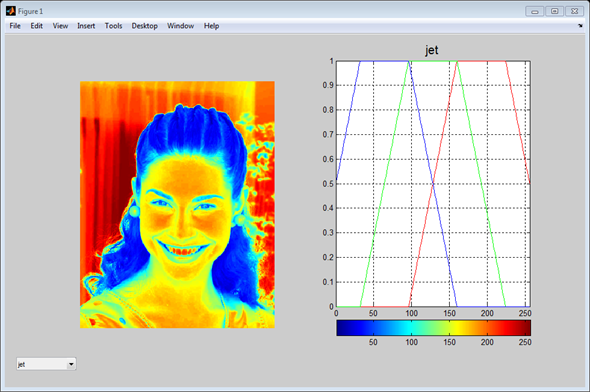

Przykład wyświetlenia dwóch elementów w jednym oknie:

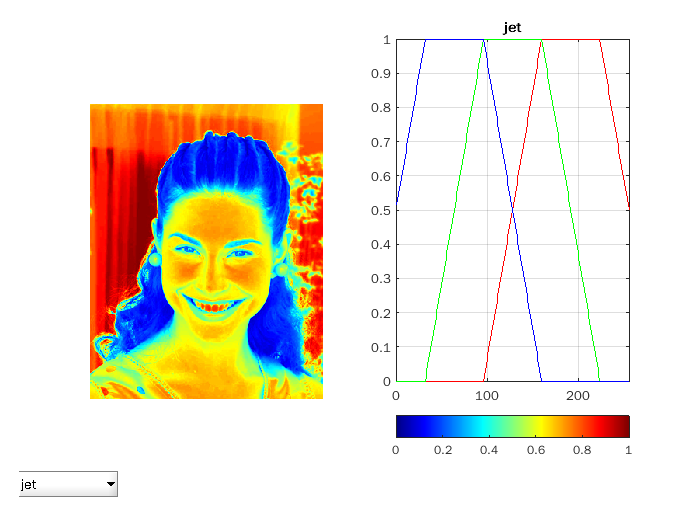

L1=imread('data/portret.jpg'); 
figure(1);
subplot(1,2,1),imshow(L1)
subplot(1,2,2),rgbplot(jet);
title("jet")
axis([0 256 0 1]); 
grid;
colormap(jet)
colorbar ('horiz');

uicontrol(1,'Style', 'popup',...
           'String', 'jet|hsv|winter|cool|autumn|summer|parula',...
           'Position', [20 1 100 50],...
           'Callback', @setmap);


%setmap.m

% function setmap(h,event) 
%     val = get(h,'Value');
%     switch val
%         case 1
%             colormap(jet)
%             rgbplot(jet)
%             title("jet")
%             axis([0 256 0 1]); 
%             grid;
%             colorbar ('horiz');
%         case 2 
%             colormap(hsv)
%             rgbplot(hsv)
%             title("hsv")
%             axis([0 256 0 1]); 
%             grid;
%             colorbar ('horiz');
%         case 3
%             colormap("winter")
%             rgbplot(winter)
%             title("winter")
%             axis([0 256 0 1]); 
%             grid;
%             colorbar ('horiz');
%         case 4
%             colormap(cool)
%             rgbplot(cool)
%             title("cool")
%             axis([0 256 0 1]); 
%             grid;
%             colorbar ('horiz');
%         case 5
%             colormap("autumn")
%             rgbplot(autumn)
%             title("autumn")
%             axis([0 256 0 1]); 
%             grid;
%             colorbar ('horiz');
%         case 6
%             colormap("summer")
%             rgbplot(summer)
%             title("summer")
%             axis([0 256 0 1]); 
%             grid;
%             colorbar ('horiz');
%         case 7
%             colormap("parula")
%             rgbplot(parula)
%             title("parula")
%             axis([0 256 0 1]); 
%             grid;
%             colorbar ('horiz');
%     end
% end


### Zadanie 2

Mapa kolorów to macierz o trzech kolumnach, z których każda zawiera 256 elementów z przedziału [0,1]. Rozbuduj poprzednie zadanie o stworzoną we własnym zakresie mapę kolorów. 

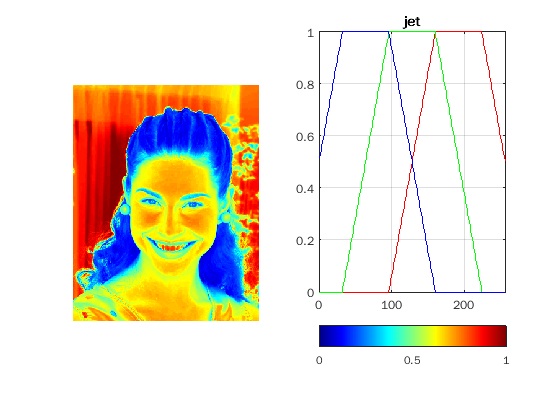

L1=imread('data/portret.jpg'); 
figure(1);
subplot(1,2,1),imshow(L1)
subplot(1,2,2),rgbplot(jet);
title("jet")
axis([0 256 0 1]); 
grid;
colormap(jet)
colorbar ('horiz');


uicontrol(1,'Style', 'popup',...
           'String', 'jet|hsv|winter|cool|autumn|summer|parula|my map',...
           'Position', [20 1 100 50],...
           'Callback', @setmap);
%setmap.m

% function setmap(h,event)
%     l = linspace(0, 1, 256);
%     R = reshape(l.^2, 256, 1);
%     G = reshape(l, 256, 1);
%     B = reshape(l, 256, 1);
%     mymap = [R G B];
%     val = get(h,'Value');
%     switch val
%         case 1
%             colormap(jet)
%             rgbplot(jet)
%             title("jet")
%             axis([0 256 0 1]); 
%             grid;
%             colorbar ('horiz');
%         case 2 
%             colormap(hsv)
%             rgbplot(hsv)
%             title("hsv")
%             axis([0 256 0 1]); 
%             grid;
%             colorbar ('horiz');
%         case 3
%             colormap("winter")
%             rgbplot(winter)
%             title("winter")
%             axis([0 256 0 1]); 
%             grid;
%             colorbar ('horiz');
%         case 4
%             colormap(cool)
%             rgbplot(cool)
%             title("cool")
%             axis([0 256 0 1]); 
%             grid;
%             colorbar ('horiz');
%         case 5
%             colormap("autumn")
%             rgbplot(autumn)
%             title("autumn")
%             axis([0 256 0 1]); 
%             grid;
%             colorbar ('horiz');
%         case 6
%             colormap("summer")
%             rgbplot(summer)
%             title("summer")
%             axis([0 256 0 1]); 
%             grid;
%             colorbar ('horiz');
%         case 7
%             colormap("parula")
%             rgbplot(parula)
%             title("parula")
%             axis([0 256 0 1]); 
%             grid;
%             colorbar ('horiz');
%         case 8 
%             colormap(mymap)
%             rgbplot(mymap)
%             title("my map")
%             axis([0 256 0 1]); 
%             grid;
%             colorbar ('horiz');
%     end
% end

### Zadanie 3

Utwórz dwa sztuczne obrazy o rozmiarze 2x2 piksele i następującym układzie kolorów: 

 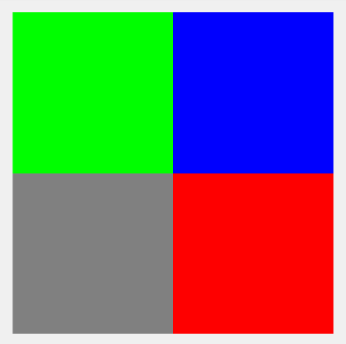                                            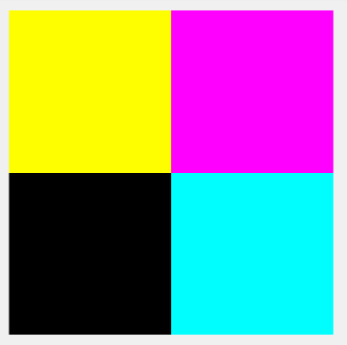

R1 = [0 0; 0.5 1]

R1 =          0         0
    0.5000    1.0000


R2 = [1 1; 0 0]

R2 =      1     1
     0     0


G1 = [1 0; 0.5 0]

G1 =     1.0000         0
    0.5000         0


G2 = [1 0; 0 1]

G2 =      1     0
     0     1


B1 = [0 1; 0.5 0]

B1 =          0    1.0000
    0.5000         0


B2 = [0 1; 0 1]

B2 =      0     1
     0     1



i1 = cat(3, R1, G1, B1)

i1 = i1(:,:,1) =

         0         0
    0.5000    1.0000


i1(:,:,2) =

    1.0000         0
    0.5000         0


i1(:,:,3) =

         0    1.0000
    0.5000         0


i2 = cat(3, R2, G2, B2)

i2 = i2(:,:,1) =

     1     1
     0     0


i2(:,:,2) =

     1     0
     0     1


i2(:,:,3) =

     0     1
     0     1


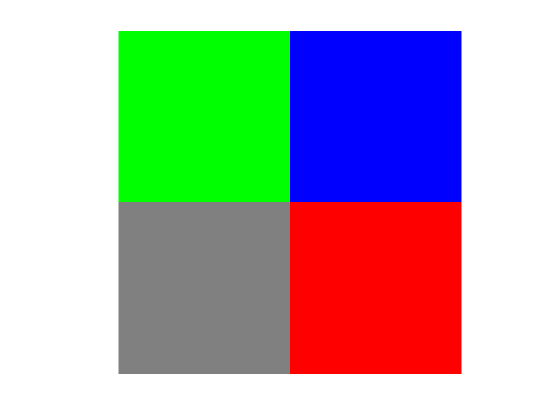

figure()
imshow(i1,'InitialMagnification','fit')

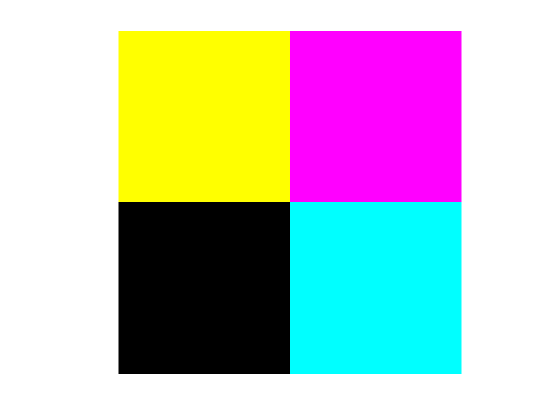

figure()
imshow(i2,'InitialMagnification','fit')

*imshow(m,'InitialMagnification','fit') - powiększenie obrazu do rozmiaru okna graficznego*

### **Przykład 2**

Zmiana poziomu jasności obrazu za pomocą suwaka

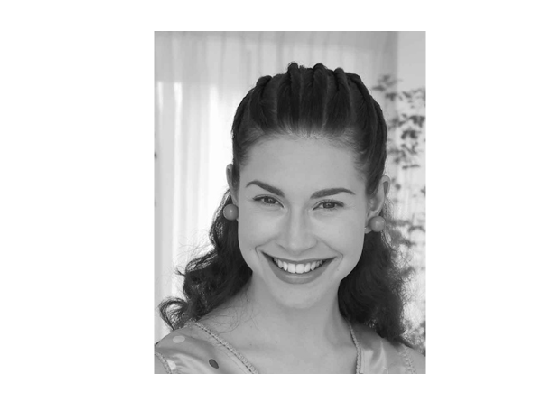

L1 = imread('data/portret.jpg');
figure; imshow(L1);
L1 = double(L1)/255;
hold on

w = 0.4

w = 0.4000

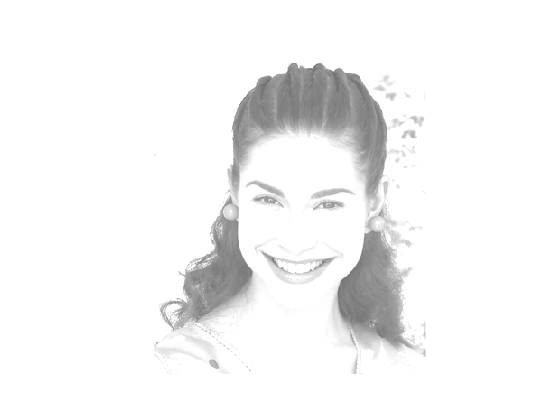

L2 = L1; L2 = L2 + w; imshow(L2);

**Wersja alternatywna**

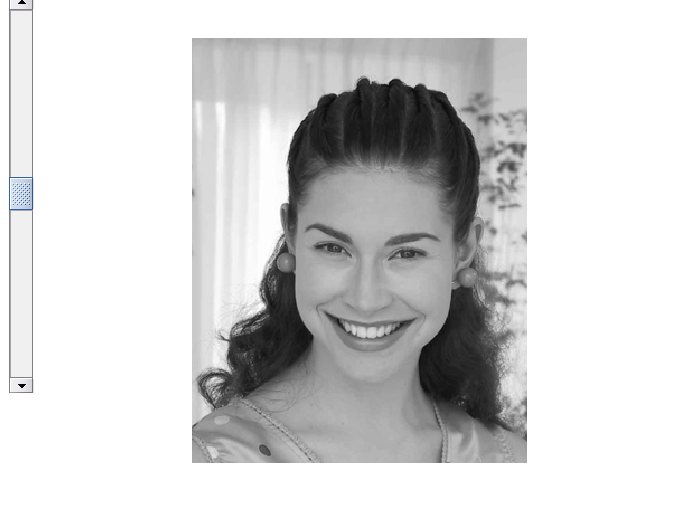

L1 = imread('data/portret.jpg');
figure; imshow(L1);
L1 = double(L1)/255;
hold on
setbright = ['w = get(suwak,''Value''); L2 = L1; L2 = L2 + w; imshow(L2)'];
suwak = uicontrol('Style','Slider',...
    'Position',[10 40 25 400],...
    'Min',-1,'Max',1,'Value',0,...
    'Callback',setbright);

### Zadanie 4

Stwórz program, w którym za pomocą trzech suwaków będzie można regulować na obrazie intensywność składowych R, G i B. Wypróbuj działanie programu na obrazie *kwiaty.jpg *

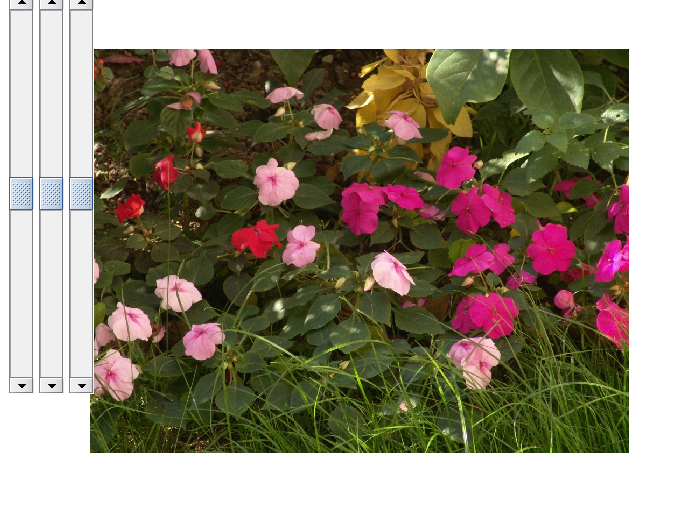

L1 = imread('data/kwiaty.jpg');
figure; imshow(L1);
L1 = double(L1)/255;
hold on
setRed = ['w = get(suwakR,''Value''); L2(:, :, 1) = L1(:, :, 1); L2(:, :, 1) = L2(:, :, 1) + w; imshow(L2)'];
setGreen = ['w = get(suwakG,''Value''); L2(:, :, 2) = L1(:, :, 2); L2(:, :, 2) = L2(:, :, 2) + w; imshow(L2)'];
setBlue = ['w = get(suwakB,''Value''); L2(:, :, 3) = L1(:, :, 3); L2(:, :, 3) = L2(:, :, 3) + w; imshow(L2)'];

suwakR = uicontrol('Style','Slider',...
    'Position',[10 40 25 400],...
    'Min',-1,'Max',1,'Value',0,...
    'Callback',setRed);

suwakG = uicontrol('Style','Slider',...
    'Position',[40 40 25 400],...
    'Min',-1,'Max',1,'Value',0,...
    'Callback',setGreen);

suwakB = uicontrol('Style','Slider',...
    'Position',[70 40 25 400],...
    'Min',-1,'Max',1,'Value',0,...
    'Callback',setBlue);